# Live Script in project Is Camel Case

Is a sequence a travel in a mesh

clear all
close('all')

## Extract Travels from Models

NofStartsInModel = 10;
RunLengthFraction = 0.1;
R = RandStream("mlfg6331_64","Seed",0);
MainFolder = fullfile("outputs","models");
Table = readtable(fullfile(MainFolder,"SimplifiedModels.xlsx"),"ReadVariableNames",true,"PreserveVariableNames",true);
Table.name = string(Table.name);
Table.reducedName = "M"+Table.index+".stl";
Table.folder = categorical(string(Table.folder));

Travels = cell(NofStartsInModel*height(Table),1);
Types   = repmat(categorical("model"),numel(Travels),1);
Counter = 0;
for t=1:height(Table)
    Model = stlread(fullfile(MainFolder,Table.reducedName(t)));
    Points = Model.Points - min(Model.Points);
    Points = Points ./ max(Model.Points);
%     List = [ Model.ConnectivityList(:,[1 2]);
%              Model.ConnectivityList(:,[2 1]);
%              Model.ConnectivityList(:,[2 3]);
%              Model.ConnectivityList(:,[3 2]);
%              Model.ConnectivityList(:,[1 3]);
%              Model.ConnectivityList(:,[3 1])];
%     List = List(List(:,1)>List(:,2),:);
%     G = graph(List(:,1),List(:,2));
    if Table.folder(t)=="teethwrl"
        Types(Counter+(1:NofStartsInModel)) = categorical("teeth");
    end
%     StartPoints = R.randi(size(G.Nodes,1), NofStartsInModel ,1);
    StartPoints = R.randi(size(Points,1), NofStartsInModel ,1);
    for iStart = StartPoints'
        Counter=Counter+1;
        Travel = FindTravel( Model.ConnectivityList ...
            ,iStart ...
            ,ceil(size(Points,1)*RunLengthFraction) ...
            ,R) ;
        Travels{Counter} = Points(Travel,:);
        % S = bfsearch(G,iStart,"Restart",true);
        % Travels{Counter} = Points(S,:);
    end
    disp("- calculated all travels on model " + t)
end

- calculated all travels on model 1
- calculated all travels on model 2
- calculated all travels on model 3
- calculated all travels on model 4
- calculated all travels on model 5
- calculated all travels on model 6
- calculated all travels on model 7
- calculated all travels on model 8
- calculated all travels on model 9
- calculated all travels on model 10
- calculated all travels on model 11
- calculated all travels on model 12
- calculated all travels on model 13
- calculated all travels on model 14
- calculated all travels on model 15
- calculated all travels on model 16
- calculated all travels on model 17
- calculated all travels on model 18
- calculated all travels on model 19
- calculated all travels on model 20
- calculated all travels on model 21
- calculated all travels on model 22
- calculated all travels on model 23
- calculated all travels on model 24
- calculated all travels on model 25
- calculated all travels on model 26
- calculated all travels on model 27
- calculat

Noise = InventNoise(R,Travels);

save("TravelsAndNoise.mat","Travels","Types","Noise",'-v7.3');

clear all
close('all')
load("TravelsAndNoise.mat","Travels","Types");

t = 375

t = 375

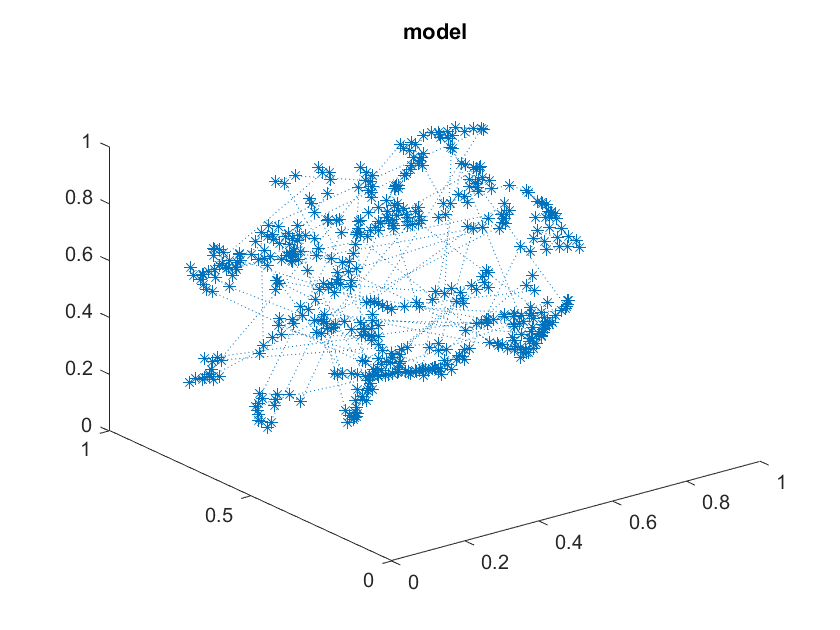

clf
Points = Travels{t};
plot3(Points(:,1),Points(:,2),Points(:,3),':*')        
title(string(Types(t)))    

## Start with Canned Example

clear all
close('all')

load("TravelsAndNoise.mat","Travels","Types","Noise");
XData = [Travels; Noise];
for i=1:numel(XData)
    XData{i}=XData{i}';
end
YData = [Types; 
         repmat(categorical("Noise"),numel(Noise),1)];

numHiddenUnits = 30;
Layers = [ ...
    sequenceInputLayer( 3 )
    bilstmLayer(numHiddenUnits,'OutputMode','last')
    fullyConnectedLayer( 3 )
    softmaxLayer
    classificationLayer];

maxEpochs = 100;
miniBatchSize = 100;

Options = trainingOptions('adam', ...
    'ExecutionEnvironment','cpu', ...
    'GradientThreshold',1, ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'SequenceLength','longest', ...
    'Shuffle','every-epoch', ...
    'Verbose',1, ...
    'Plots','training-progress');

net = trainNetwork(XData,YData,Layers,Options);

Error using trainNetwork (line 183)
Invalid training data. Predictors must be a N-by-1 cell array of sequences, where N is the number of sequences. All sequences must have the same feature dimension and at least one time step.

function Travel = FindTravel(Faces,iStart,RunLength,R)
    arguments
        Faces     (:,3) uint16 % assuming a reduced model at input
        iStart    (1,1) uint16
        RunLength (1,1) uint16
        R % randomaizer
    end
    Travel = zeros(RunLength,1,'uint16');
    Index = Faces(iStart);
    
    for i=2:RunLength
        Travel(i-1) = Index;
%        disp("Travel("+(i-1)+")=" + Index)

In which faces can we find this point?    

        PointAt = find(Faces(:)==Index);   
        assert(~isempty(PointAt))
%        disp(numel(PointAt)+" occurences found")

Never visit this point again. 

All faces with just one point become unuseful

        Faces(Faces==Index)=0;
%        disp(nnz(N==0) + "==0, " + nnz(N==1) + "==1, " + nnz(N==2) + "==2")

Not a dead -end. Which face was it?

       [FaceNo,i123] = ind2sub(size(Faces) ...
       ,PointAt(R.randi(numel(PointAt),1,1)));
 %      disp("Selected occurence at " + FaceNo + ", " + i123)

hoose a neighbour

        Others = Faces(FaceNo,setdiff(1:3,i123));
        Others = Others(Others~=0);
        switch numel(Others)
            case 0

Have we reached a dead-end? Must restart from a new random point              

                N = sum(uint8(Faces>0),2);        
                Faces = Faces(N>1,:);
                U = unique(Faces(Faces(:)>0));
                Index = U(R.randi(numel(U),1,1));
%                disp("Dead-end, " + size(Faces,1) + "faces remain, jump to + " + Index)
            case 1
                Index = Others;
            case 2
                Index = Others(R.randi(2,1,1));
        end
%        disp("Selected neighbour " + Index + " of " + numel(Others))
    end
    Travel(RunLength) = Index;
end

function Noise = InventNoise(R,Travels)
    Noise = cell(size(Travels));
    for n=1:numel(Noise)
        Noise{n} = R.randn(size(Travels{n},1),3);
        Noise{n} = Noise{n} - min(Noise{n}); 
        Noise{n} = Noise{n}./ max(Noise{n}); 
    end
end